#  Running MONAI model inference in MATLAB

This document walks through the process of importing an image segmentation model trained using MONAI into MATLAB, using two different methods with distinct pros and cons, which we will delve into next. This has been tested on Mac OS Sonoma 14.5 with MATLAB R2024a running the Intel build. To get things running, we will first setup the dependent conda environment.

Setting up the python version and environment:

terminate(pyenv)
pyversion('/Users/amithkamath/opt/anaconda3/envs/matlab-env/bin/python')

## Making available the custom written python module into MATLAB:

Importing a custom module to interact between MATLAB and functions written to load the U-Net model, and run inference.

py.importlib.import_module('matlab_monai_bridge')

ans =   Python module with properties:

                 Activations: [1×1 py.abc.ABCMeta]
    sliding_window_inference: [1×1 py.function]
                 Orientation: [1×1 py.abc.ABCMeta]
                     Compose: [1×1 py.abc.ABCMeta]
                   LoadImage: [1×1 py.abc.ABCMeta]
                  save_model: [1×1 py.function]
                   inference: [1×1 py.function]
                       torch: [1×1 py.module]
                   save_data: [1×1 py.function]
                  test_model: [1×1 py.function]
               NibabelWriter: [1×1 py.type]
                     Spacing: [1×1 py.abc.ABCMeta]
                        UNet: [1×1 py.type]
                create_model: [1×1 py.function]
               get_transform: [1×1 py.function]
                          os: [1×1 py.module]
                  AsDiscrete: [1×1 py.abc.ABCMeta]
              ScaleIntensity: [1×1 py.abc.ABCMeta]
                  

### Method 1 to import model into MATLAB:

Creating the MONAI version of the U-Net in MATLAB using the create_model function:

monaiUNet = py.matlab_monai_bridge.create_model("models/trained_msd_heart_model.ckpt")

sys:1: UserWarning: TypedStorage is deprecated. It will be removed in the future and UntypedStorage will be the only storage class. This should only matter to you if you are using storages directly.  To access UntypedStorage directly, use tensor.untyped_storage() instead of tensor.storage()


monaiUNet =   Python UNet with properties:

      adn_ordering: [1×3 py.str]
       in_channels: [1×1 py.int]
          training: 1
           strides: [1×5 py.tuple]
           dropout: 0
    up_kernel_size: [1×1 py.int]
          channels: [1×6 py.tuple]
              bias: 0
               act: [1×4 py.str]
      out_channels: [1×1 py.int]
       kernel_size: [1×1 py.int]
        dimensions: [1×1 py.int]
     num_res_units: [1×1 py.int]
              norm: [1×5 py.str]

    UNet(
      (model): Sequential(
        (0): Convolution(
          (conv): Conv3d(1, 16, kernel_size=(3, 3, 3), stride=(2, 2, 2), padding=(1, 1, 1), bias=False)
          (adn): ADN(
            (N): BatchNorm3d(16, eps=1e-05, momentum=0.1, affine=True, track_running_stats=True)
            (D): Dropout(p=0.0, inplace=False)
            (A): ReLU()
          )
        )
        (1): SkipConnection(
          (submodule):

Reading image data (the size of which corresponds to the model previously trained):

image_path = "data/la_030.nii.gz";
img = niftiread(image_path);

gt_label = niftiread("data/tformed_label_la_030.nii.gz");

% Display the volume and ground truth labels using Volume Segmenter:
% volumeSegmenter

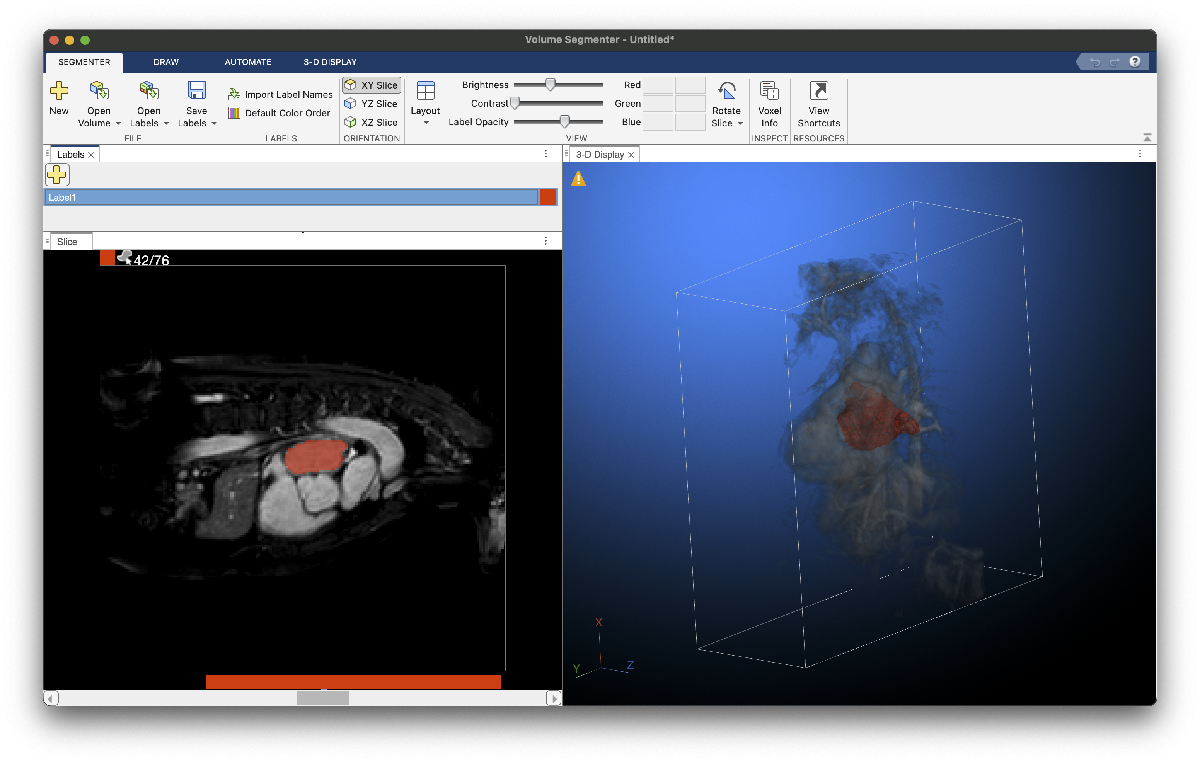

Running inference using the python function from the custom imported module:

seg = py.matlab_monai_bridge.inference(monaiUNet, image_path);

Displaying the segmentation results along with the image:

seg_array = squeeze(logical(py.numpy.array(seg)));
size(seg_array)

ans =      2   200   200    76


Evaluate performance of model using Dice score coefficient:

dice(squeeze(seg_array(2, :, :, :)), logical(gt_label))

ans = 0.8601

## Method 2 to import model into MATLAB:

This model can also be displayed in deep network designer:

model = importNetworkFromPyTorch("models/msd_heart_model.pt");


% Display model with Deep Network Designer:
%deepNetworkDesigner(model)

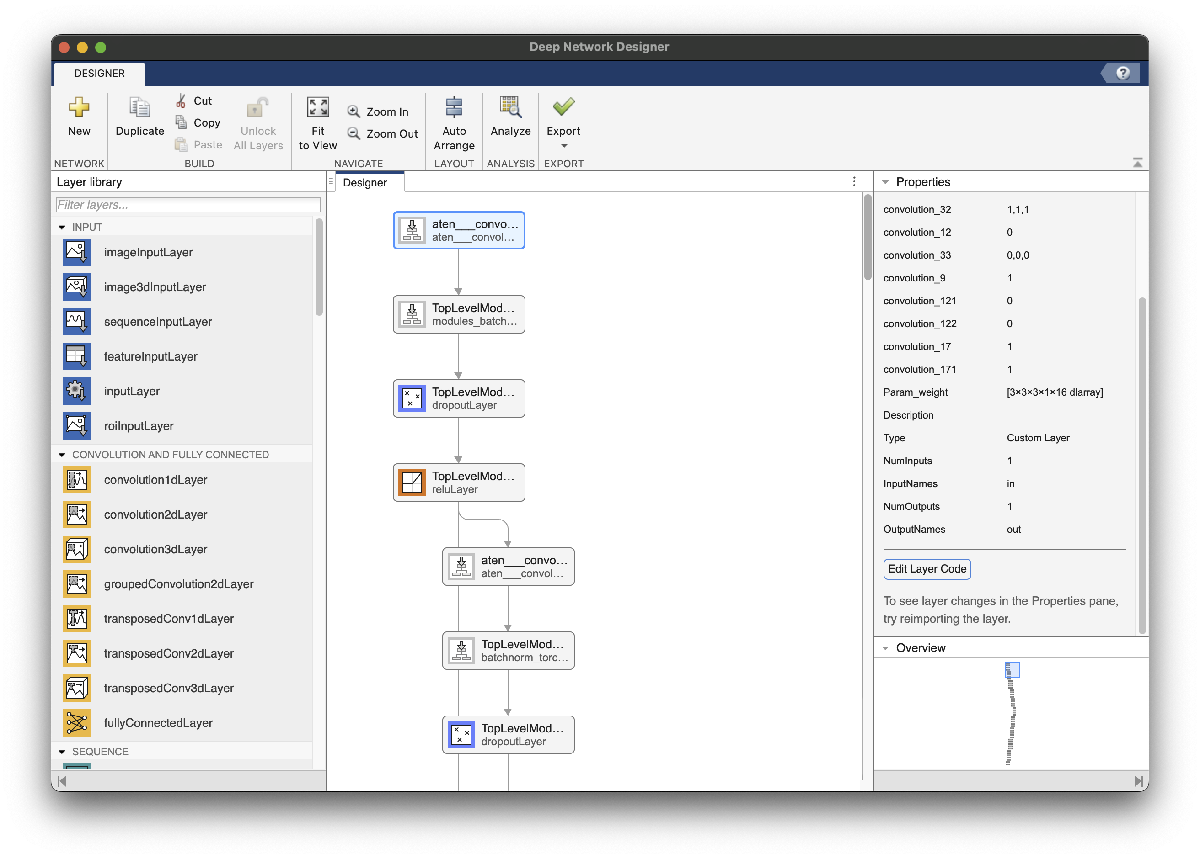

*Copyright 2024 The MathWorks Inc.*